# Input/Output Characterization

clc
clear all
close all

x = [0, 10, 15,20,  25  30,   35,   40,  45,   50,   60];
y = [0, 0.3, 0.67 , 1.1, 1.32, 1.43, 1.64, 1.78, 1.92, 2.04, 2.14];

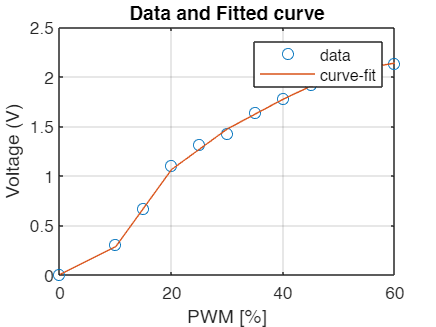

% fit the data
c = polyfit(x,y,6);
% generate fitted curve
xfit = 0:10:60;
yfit = polyval(c,xfit);
% plot the original data as symbols and fitted curve as connected line
figure % open a new figure for the plot
plot(x,y,'o',xfit,yfit,'-')
legend({'data','curve-fit'})
xlabel('PWM [%]')
ylabel('Voltage (V)')
title('Data and Fitted curve')
grid on